## NUMERICAL EXAMPLES

### WEIGHTING THE GOLD

Our initial guess (by reading the stamp on the gold bar) of the gold bar weight is 1000 gram. The initial guess is used only once for the filter initiation, thus it won't be required for the next iterations.

%Initialization
initialGuess = 1000; %gram
%x_0_0= 1000;

The weight of the gold bar is not supposed to change. Therefore, the dynamic model of the system is static. Our next state estimate (prediction) equals to the initialization:

%Prediction
predictedValue = 1000;
%x_1_0 = x_0_0;

Before initialize the iteration; let's create an array contains the measurement values.

%z values for each iteration
mesasurements = [1030 989 1017 1009 1013 979 1008 1042 1012 1011];

%Create empty arrays to store iteration values
gains = [];
currentEstimates = [];
predictedValues = [];

%Iteration begins
for i=1:10
    %Step 1
    % Make measurement:
    z = mesasurements(i);
    %Step 2
    % Calculate the gain. (a_n value):
    a = 1/i;
    gains(i)=a;
    % Calculating the current estimate using the state update equation:
    currentEstimate = predictedValue + a * (z - predictedValue); %x_i_i
    currentEstimates(i)=currentEstimate;
    %Step 3
    % The dynamic model of the system is static, thus the weight of the gold bar is not supposed to change.
    % Our next state estimate (prediction) equals to the current state estimate:
    predictedValue = currentEstimate; %x_(i+1)_i
    predictedValues(i) = predictedValue;
end

Let's figure it,

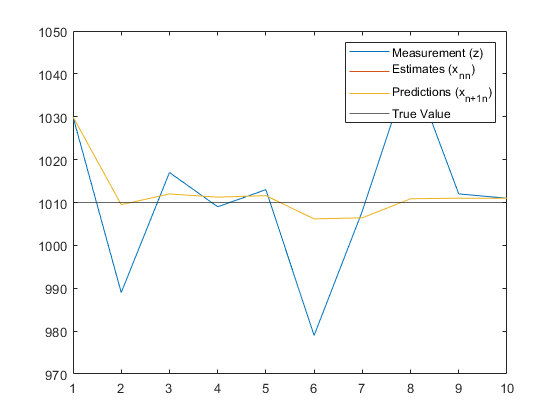

figure();
plot(mesasurements,"DisplayName","Measurement (z)");
hold on;
plot(currentEstimates,"DisplayName","Estimates (x_n_n)");
hold on;
plot(predictedValues,"DisplayName","Predictions (x_{n+1}_n)");
hold on;
yline(1010,"DisplayName","True Value");
hold off;
ylim([970 1050]);
legend;

### TRACKING THE CONSTANT VELOCITY AIRCRAFT IN ONE DIMENSION

Now, it is time to examine a dynamic system that changes its state over the time. In this example, we are going to track the constant velocity aircraft in one dimension using the **α-β filter**.

Let us assume a one-dimensional world. We assume an aircraft that is moving radially away from the radar (or towards the radar). In the one-dimensional world, the angle to the radar is constant and the altitude of the aircraft is constant, as shown on the following figure.

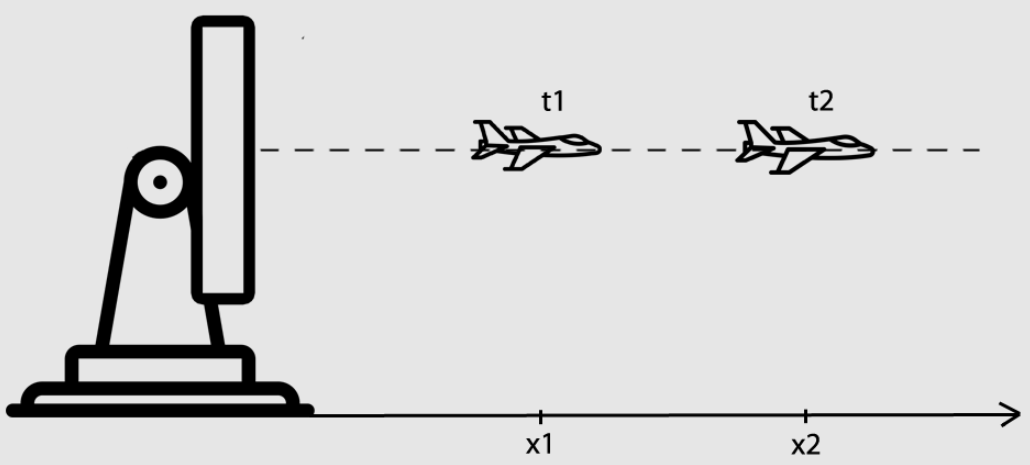

x_{n} is representing the range to the aircraft at time n. The aircraft velocity is defined as the rate of change of the range with respect to time, thus the velocity is a derivative of the range:


$$$$
\dot{x}=v=\frac{d x}{d t}
$$$$


The radar sends a track beam in the direction of the target with a constant rate. The track-to-track interval is Δt.Assuming constant velocity, the system's dynamic model can be described by two equations of motion:


$$$$
\begin{array}{c}
x_{n+1}=x_{n}+\Delta t \dot{x}_{n} \\
\dot{x}_{n+1}=\dot{x}_{n}
\end{array}
$$$$


According to the equations, the aircraft range at the next track cycle equals to the range at the current track cycle plus the target velocity multiplied by track-to-track interval. In this example, we assume constant velocity. Therefore, the velocity at the next cycle equals to the velocity at the current cycle.

The State Update Equation for the aircraft position, is similar to the equation that was derived in the previous example:


$$
$$
\hat{x}_{n, n}=\hat{x}_{n, n-1}+\alpha\left(z_{n}-\hat{x}_{n, n-1}\right)
$$$$


On contrary to the pervious example, where the αα factor is recalculated in each iteration ( αn=1Nαn=1N ), in this example the αα factor is constant.

So, we have derived a system of equations that composes the Update State Equation for the radar tracker. They are also called α−βα−β** track update equations** or α−βα−β** track filtering equations**.

The Update State Equation for position:


$$$$
\hat{x}_{n, n}=\hat{x}_{n, n-1}+\alpha\left(z_{n}-\hat{x}_{n, n-1}\right)
$$
The Update State Equation for velocity:
$$
\hat{\dot{x}}_{n, n}=\hat{\dot{x}}_{n, n-1}+\beta\left(\frac{z_{n}-\hat{x}_{n, n-1}}{\Delta t}\right)
$$$$


% Initialize parameters
alfa = 0.2; %0.2 default
beta = 0.1; %0.1 default
ttInterval = 5; %secs %Track-to-Track interval %5 default

initalDistance = 30000; %meter
initialVelocity = 40; %m/s

predictedDistance = initalDistance +  (initialVelocity * ttInterval);
predictedVelocity = initialVelocity;

Before initialize the iteration; let's create arrays for storing the measurement and estimation values.

mesaurements = [30110 30265	30740 30750 31135 31015 31180 31610 31960 31865];
estimationDistances = [];
estimationVelocities = [];
predictionDistances = [];
predictionVelocities = [];

for i=1:10
    %Radar measurement
    z = mesaurements(i);    
    
    %Estimates
    estimateDistance = predictedDistance + alfa*(z-predictedDistance);
    estimateVelocity = predictedVelocity + beta*((z-predictedDistance)/ttInterval);
    estimationDistances(i)=estimateDistance;
    estimationVelocities(i)=estimateVelocity;
    
    %Prediction
    predictedDistance = estimateDistance + ttInterval*estimateVelocity;
    predictedVelocity = estimateVelocity;
    predictionDistances(i)=predictedDistance;
    predictionVelocities(i)=predictedVelocity;
    
end

Let's figure it,

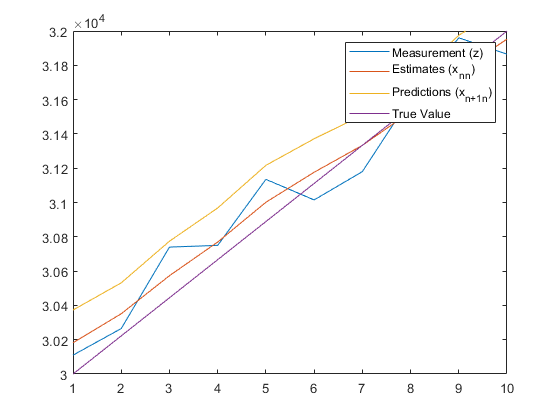

figure();
plot(mesaurements,"DisplayName","Measurement (z)");
hold on;
plot(estimationDistances,"DisplayName","Estimates (x_n_n)");
hold on;
plot(predictionDistances,"DisplayName","Predictions (x_{n+1}_n)");
hold on;
trueDistances = linspace(30000,32000,10);
plot(trueDistances,"DisplayName","True Value");
hold off;
ylim([30000 32000]);
legend;

**USING HIGH** α **AND** β

The code above can be run for α=0.8 and β=0.5.

he value of α and β shall depend on the measurement precision. If we use very precise equipment, like the laser radar, we would prefer high α and β that follow measurements. 

### TRACKING ACCELERATING AIRCRAFT IN ONE DIMENSION

In this example, we are going to track the aircraft that is moving with constant acceleration with the α−β filter that was already explained in the previous example.

In the previous example, we've tracked the UAV that is moving at constant velocity of 40m/s. The following chart depicts the target range and velocity vs. time.

Now let's examine a fighter aircraft. This aircraft moves with the constant velocity of 50m/s for 15 seconds. Then the aircraft accelerates with constant acceleration of 8m/s2 for another 35 seconds.

We are going to track this aircraft with the α-β filter that was used in the previous example.

Before begin, define our true measurement values;

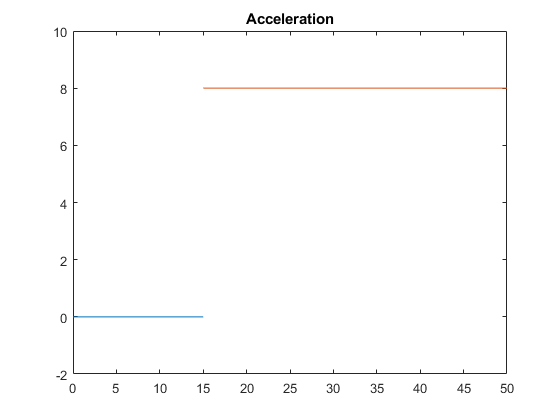

% We are using the same variable names with the previous example,
% Before begin, let's clear them to prevent possible confusions.
clc;
clear;
dt = 5; %sec
time15 = 0:dt:15; %Time domain for first 15 seconds
time50 = 15:dt:50; %Time domain for last 35 seconds

acc15 = zeros(1,length(time15)); %Acceleration for first 15 secs
acc50 = ones(1,length(time50))*8; %Acceleration for last 35 secs
figure();
plot(time15,acc15,time50,acc50);
title("Acceleration");
ylim([-2 10]);

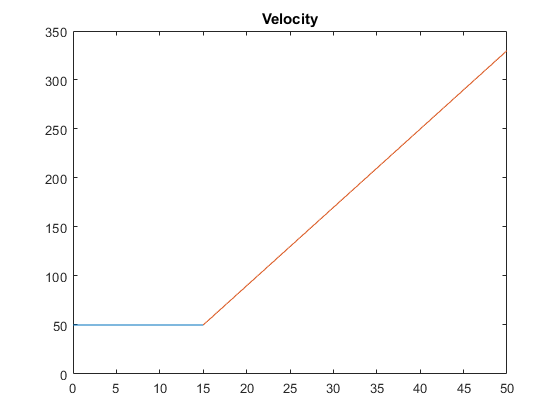


vel15 = 50+cumtrapz(acc15)*dt; %Velocity for first 15 secs
vel50 = vel15(end)+cumtrapz(acc50)*dt; %Velocity for last 35 secs
figure();
plot(time15,vel15,time50,vel50);
title("Velocity");
ylim([0 350]);

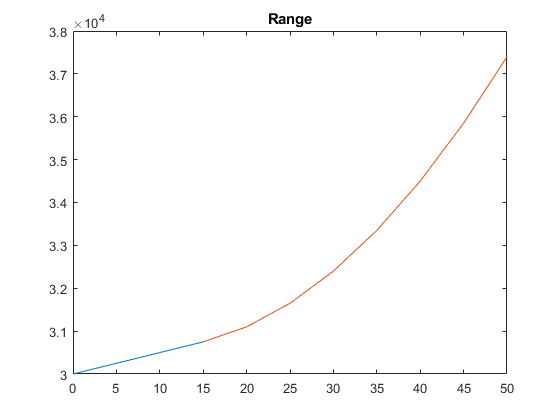


range15 = 30000+(cumtrapz(vel15)*dt);
range50 = range15(end)+(cumtrapz(vel50)*dt);
figure();
plot(time15,range15,time50,range50);
title("Range");

Now, let's continue with the filter,

% Initialize parameters
alfa = 0.2; %0.2 default
beta = 0.1; %0.1 default
ttInterval = 5; %secs %Track-to-Track interval %5 default

initalDistance = 30000; %meter
initialVelocity = 50; %m/s

predictedDistance = initalDistance +  (initialVelocity * ttInterval);
predictedVelocity = initialVelocity;

Before initialize the iteration; let's create arrays for storing the measurement and estimation values.

mesaurements = [30160 30365	30890 31050 31785 32215 33130 34510 36010 37265];
estimationDistances = [];
estimationVelocities = [];
predictionDistances = [];
predictionVelocities = [];

for i=1:10
    %Radar measurement
    z = mesaurements(i);    
    
    %Estimates
    estimateDistance = predictedDistance + alfa*(z-predictedDistance);
    estimateVelocity = predictedVelocity + beta*((z-predictedDistance)/ttInterval);
    estimationDistances(i)=estimateDistance;
    estimationVelocities(i)=estimateVelocity;
    
    %Prediction
    predictedDistance = estimateDistance + ttInterval*estimateVelocity;
    predictedVelocity = estimateVelocity;
    predictionDistances(i)=predictedDistance;
    predictionVelocities(i)=predictedVelocity;
    
end

Let's figure the displacement,

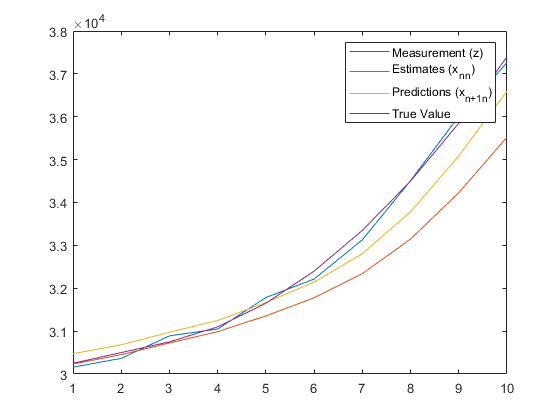

figure();
plot(mesaurements,"DisplayName","Measurement (z)");
hold on;
plot(estimationDistances,"DisplayName","Estimates (x_n_n)");
hold on;
plot(predictionDistances,"DisplayName","Predictions (x_{n+1}_n)");
hold on;
range = [range15(2:end-1) range50(1:end)];
plot(range,"DisplayName","True Value");
%plot(trueDistances,"DisplayName","True Value");
hold off;
%ylim([30000 32000]);
legend;

Let's figure the velocity,

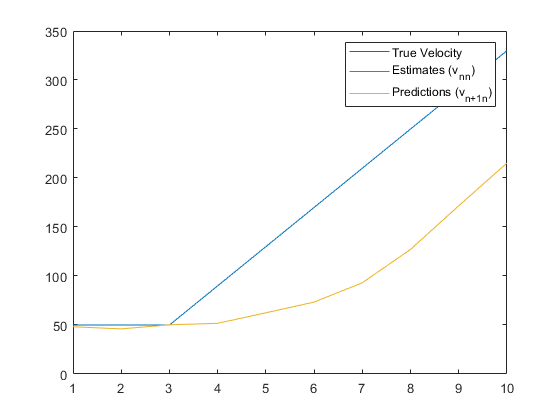

figure();
vel = [vel15(2:end-1) vel50];
plot(vel,"DisplayName","True Velocity");
hold on;
plot(estimationVelocities,"DisplayName","Estimates (v_n_n)");
hold on;
plot(predictionVelocities,"DisplayName","Predictions (v_{n+1}_n)");
hold off;
%ylim([30000 32000]);
legend;

You can see a constant gap between the true or measured values and the estimated values. The gap is called a **lag error**.

### TRACKING ACCELERATING AIRCRAFT WITH THE α−β−γ FILTER

In this example, we are going to track the aircraft that is moving with constant acceleration with the α−β−γ filter. The α−β−γ** filter** (sometimes called **g-h-k filter**) considers target acceleration.

Let's take the scenario from the previous example: the aircraft that moves with the constant velocity of 50m/s for 15 seconds. Then the aircraft accelerates with constant acceleration of 8m/s2 for another 35 seconds.

The α - β filter parameters are:

- α=0.5

- β=0.4

- γ=0.1

The track-to-track interval is 5 seconds.

Let's simulate the movement first,

% We are using the same variable names with the previous example,
% Before begin, let's clear them to prevent possible confusions.
clc;
clear;
dt = 5; %sec
time15 = 0:dt:15; %Time domain for first 15 seconds
time50 = 15:dt:50; %Time domain for last 35 seconds

acc15 = zeros(1,length(time15)); %Acceleration for first 15 secs
acc50 = ones(1,length(time50))*8; %Acceleration for last 35 secs
figure();
plot(time15,acc15,time50,acc50);
title("Acceleration");
ylim([-2 10]);


vel15 = 50+cumtrapz(acc15)*dt; %Velocity for first 15 secs
vel50 = vel15(end)+cumtrapz(acc50)*dt; %Velocity for last 35 secs
figure();
plot(time15,vel15,time50,vel50);
title("Velocity");
ylim([0 350]);


range15 = 30000+(cumtrapz(vel15)*dt);
range50 = range15(end)+(cumtrapz(vel50)*dt);
figure();
plot(time15,range15,time50,range50);
title("Range");

Now, let's continue with the filter,

% Initialize parameters
alfa = 0.5; %0.2 default
beta = 0.4; %0.1 default
gama = 0.1;
ttInterval = 5; %secs %Track-to-Track interval %5 default

initalDistance = 30000; %meter
initialVelocity = 50; %m/s
initialAcceleration = 0; %m/s2

predictedDistance = initalDistance +  (initialVelocity * ttInterval) + (0.5*initialAcceleration*(ttInterval^2));
predictedVelocity = initialVelocity + (initialAcceleration * ttInterval);
predictedAcceleration = initialAcceleration;

Before initialize the iteration; let's create arrays to store the measurement and estimation values.

mesaurements = [30160 30365	30890 31050 31785 32215 33130 34510 36010 37265];
estimationDistances = [];
estimationVelocities = [];
predictionDistances = [];
predictionVelocities = [];

for i=1:10
    %Radar measurement
    z = mesaurements(i);    
    
    %Estimates
    estimateDistance = predictedDistance + alfa*(z-predictedDistance);
    estimateVelocity = predictedVelocity + beta*((z-predictedDistance)/ttInterval);
    estimateAcceleration = predictedAcceleration + gama*((z-predictedDistance)/(0.5*(ttInterval^2)));
    estimationDistances(i)=estimateDistance;
    estimationVelocities(i)=estimateVelocity;
    estimationAccelerations(i)=estimateAcceleration;
    
    %Prediction
    predictedDistance = estimateDistance + (ttInterval*estimateVelocity) + (estimateAcceleration*(ttInterval^2)*0.5);
    predictedVelocity = estimateVelocity + estimateAcceleration * ttInterval;
    predictedAcceleration = estimateAcceleration;    
    predictionDistances(i)=predictedDistance;
    predictionVelocities(i)=predictedVelocity;    
    predictionAccelerations(i)=predictedAcceleration;
end

Let's figure the displacement,

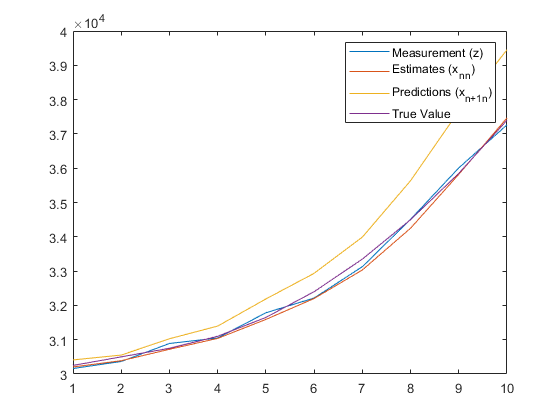

figure();
plot(mesaurements,"DisplayName","Measurement (z)");
hold on;
plot(estimationDistances,"DisplayName","Estimates (x_n_n)");
hold on;
plot(predictionDistances,"DisplayName","Predictions (x_{n+1}_n)");
hold on;
range = [range15(2:end-1) range50(1:end)];
plot(range,"DisplayName","True Value");
%plot(trueDistances,"DisplayName","True Value");
hold off;
%ylim([30000 32000]);
legend;

Let's figure the velocity,

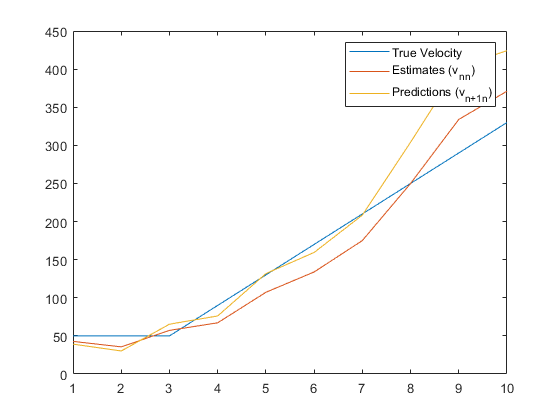

figure();
vel = [vel15(2:end-1) vel50];
plot(vel,"DisplayName","True Velocity");
hold on;
plot(estimationVelocities,"DisplayName","Estimates (v_n_n)");
hold on;
plot(predictionVelocities,"DisplayName","Predictions (v_{n+1}_n)");
hold off;
%ylim([30000 32000]);
legend;

You can see a constant gap between the true or measured values and the estimated values. The gap is called a **lag error**.